# C2型量子群の表現を構築するための代数構造の多項式表示

## 動機

C2型量子群のmodule algebraは非可換変数としては既に得られている。これを可換変数で表示したい。

そのために可換変数で積構造の微分演算子による表示を解析する。

quantum symplectic spaceの定義

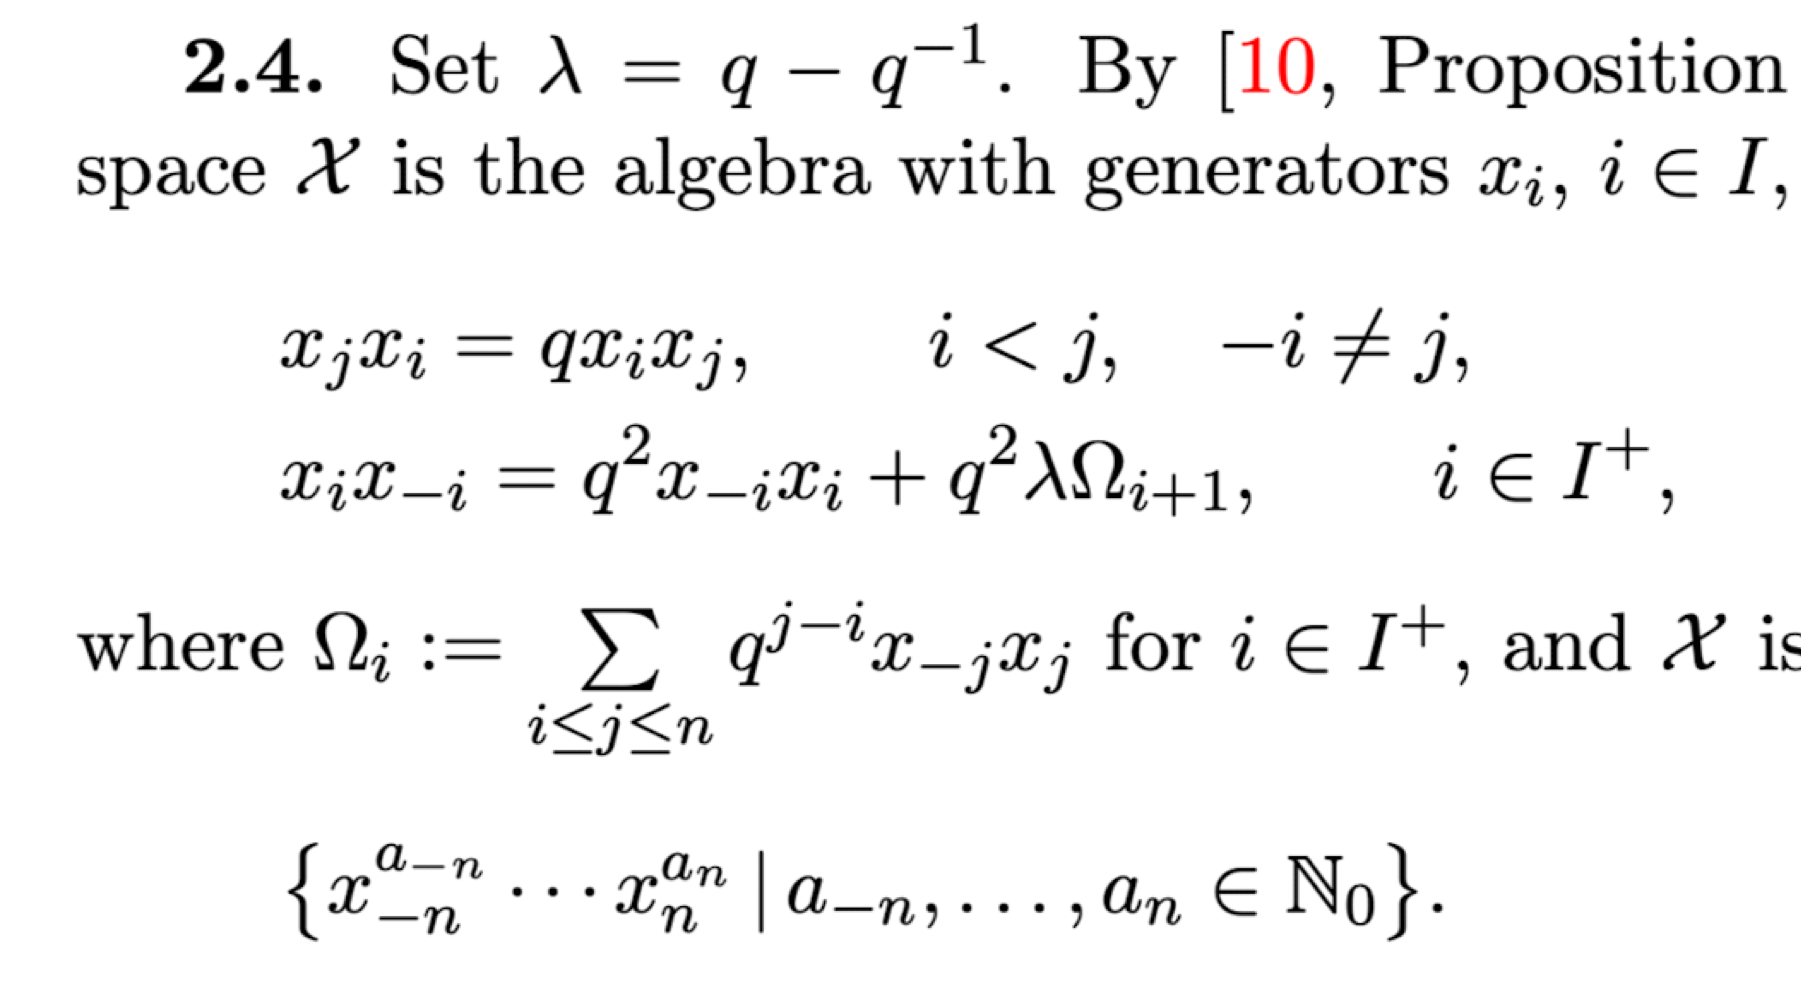

今回はn=2(ll=2)の場合で解析を行う。

symC2alg.mが今回の代数構造に該当するsymp継承クラスである。


ll=2;
set(CR.H,display=1);
v=rowfun(@(x)symC2alg(1,x),table(eye(4)));
v=dictionary([-ll:-1,1:ll]',v.Var1);


v(-2)*v(2)

ans =     coeff    p_1    p_2    p_3    p_4
    _____    ___    ___    ___    ___
      1       1      0      0      1 

v(2)*v(-2)

ans =     coeff    p_1    p_2    p_3    p_4
    _____    ___    ___    ___    ___
     q^2      1      0      0      1 

v(2)*v(-1)

ans =     coeff    p_1    p_2    p_3    p_4
    _____    ___    ___    ___    ___
      q       0      1      0      1 

v(1)*v(-1)

ans =        coeff       p_1    p_2    p_3    p_4
    ___________    ___    ___    ___    ___
    q^2             0      1      1      0 
    q*(q^2 - 1)     1      0      0      1 

v(-1)*v(1)

ans =     coeff    p_1    p_2    p_3    p_4
    _____    ___    ___    ___    ___
      1       0      1      1      0 

syms q
qN=qNumS(q);
s=@simplify;
tau=qN.T;
QN=@qN.n;

非自明な乗算がq-expで書けるということを見る。

a=v(1)^2*v(-1)^2;
s(a.cf.'./[1,qN.n(2)^2,qN.n(2)]./(tau.^(0:2))/q^8)

$$ans = \left(\begin{array}{ccc} 1 & 1 & \frac{1}{q} \end{array}\right)$$

a=v(1)^3*v(-1)^3;
s(a.cf.'./[1,qN.n(3)^2,qN.n(3)^2*qN.n(2),qN.fac(3)]./(tau.^(0:3))/q^18)

$$ans = \left(\begin{array}{cccc} 1 & 1 & \frac{1}{q} & \frac{1}{q^{3}} \end{array}\right)$$

a=v(1)^5*v(-1)^3;
s(a.cf.'./[1,QN(5)*QN(3),QN(5)*QN(4)*QN(3),QN(5)*QN(4)*QN(3)]./(tau.^(0:3))/q^30)

$$ans = \left(\begin{array}{cccc} 1 & 1 & \frac{1}{q} & \frac{1}{q^{3}} \end{array}\right)$$

乗算表の作成

## 積のq倍のひねり

M=repmat(v(1)*0,4,4);
index=[-2 -1 1 2];
for ii=1:4
    for jj=1:4
        M(ii,jj)=(v(index(ii))*v(index(jj)));
    end
end
M(3,2)=v(1);
M(3,2).cf=q^2;
reshape([M.cf],4,4)

$$ans = \left(\begin{array}{cccc} 1 & 1 & 1 & 1\\ q & 1 & 1 & 1\\ q & q^{2} & 1 & 1\\ q^{2} & q & q & 1 \end{array}\right)$$

## 積公式(一部)


$$x_{-2}^sx_{2}^t=q^{2st}\tilde P\circ\exp_{q^{-1}}[x_1D_2\otimes x_{-1}D_{-2}] (x_2^t\otimes x_{-2}^s)$$


という公式を確認した

a=v(1)^2*v(-1)^5

a =                  coeff                 x_m2    x_m1    x_1    x_2
    _______________________________    ____    ____    ___    ___
    q^20                                0       5       2      0 
    -q^14*(- q^12 - q^10 + q^2 + 1)     1       4       1      1 
    q^28 - q^20 - q^18 + q^10           2       3       0      2 

a=v(1)^2.*v(-1)^5

a =                  coeff                 x_m2    x_m1    x_1    x_2
    _______________________________    ____    ____    ___    ___
    q^20                                0       5       2      0 
    -q^14*(- q^12 - q^10 + q^2 + 1)     1       4       1      1 
    q^28 - q^20 - q^18 + q^10           2       3       0      2 

## 結合律の検証

M1=repmat(v(1)*0,4,4,4);
M2=repmat(v(1)*0,4,4,4);
index=[-2 -1 1 2];
for ii=1:4
    for jj=1:4
        for kk=1:4
            % (**)*
            M1(ii,jj,kk)=(v(index(ii))*v(index(jj)))*v(index(kk));
            % *(**)
            M2(ii,jj,kk)=v(index(ii))*(v(index(jj))*v(index(kk)));
        end
    end
end

O=v(1)-v(1);
Md=arrayfun(@minus,M1,M2);
Md0=arrayfun(@isequal,Md,repmat(O,4,4,4))

Md0 = 4×4×4 の logical 配列
Md0(:,:,1) =
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
Md0(:,:,2) =
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
Md0(:,:,3) =
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
Md0(:,:,4) =
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1

Md0によれば結合律が破れているので、そこを補正する。

function di(v,ii,jj,kk)    
disp2(v(ii).*v(jj).*v(kk)) %original
disp2(0+v(ii)*v(jj)*v(kk)) %(**)*
disp2(0+v(ii)*(v(jj)*v(kk))) %*(**)
end

di(v,-1,1,-1)

$$\mathrm{ans}=q^{2}\,x_{1}\,{x_{\mathrm{m1}}}^{2}+q^{2}\,x_{2}\,x_{\mathrm{m1}}\,x_{\mathrm{m2}}\,\left(q^{2}-1\right)$$

$$\mathrm{ans}=q^{2}\,x_{1}\,{x_{\mathrm{m1}}}^{2}-x_{2}\,x_{\mathrm{m1}}\,x_{\mathrm{m2}}\,\left(q^{2}-q^{4}\right)$$

$$\mathrm{ans}=q^{2}\,x_{1}\,{x_{\mathrm{m1}}}^{2}-x_{2}\,x_{\mathrm{m1}}\,x_{\mathrm{m2}}\,\left(q^{2}-q^{4}\right)$$

di(v,1,-1,-1)

$$\mathrm{ans}=q^{4}\,x_{1}\,{x_{\mathrm{m1}}}^{2}+q^{2}\,x_{2}\,x_{\mathrm{m1}}\,x_{\mathrm{m2}}\,\left(q^{4}-1\right)$$

$$\mathrm{ans}=q^{4}\,x_{1}\,{x_{\mathrm{m1}}}^{2}-x_{2}\,x_{\mathrm{m1}}\,x_{\mathrm{m2}}\,\left(q^{2}-q^{6}\right)$$

$$\mathrm{ans}=q^{4}\,x_{1}\,{x_{\mathrm{m1}}}^{2}-x_{2}\,x_{\mathrm{m1}}\,x_{\mathrm{m2}}\,\left(q^{2}-q^{6}\right)$$

di(v,1,1,-1)

$$\mathrm{ans}=q^{4}\,{x_{1}}^{2}\,x_{\mathrm{m1}}+q^{2}\,x_{1}\,x_{2}\,x_{\mathrm{m2}}\,\left(q^{4}-1\right)$$

$$\mathrm{ans}=q^{4}\,{x_{1}}^{2}\,x_{\mathrm{m1}}-x_{1}\,x_{2}\,x_{\mathrm{m2}}\,\left(q^{2}-q^{6}\right)$$

$$\mathrm{ans}=q^{4}\,{x_{1}}^{2}\,x_{\mathrm{m1}}-x_{1}\,x_{2}\,x_{\mathrm{m2}}\,\left(q^{2}-q^{6}\right)$$

di(v,1,-1,1)

$$\mathrm{ans}=q^{2}\,{x_{1}}^{2}\,x_{\mathrm{m1}}+q^{2}\,x_{1}\,x_{2}\,x_{\mathrm{m2}}\,\left(q^{2}-1\right)$$

$$\mathrm{ans}=q^{2}\,{x_{1}}^{2}\,x_{\mathrm{m1}}-x_{1}\,x_{2}\,x_{\mathrm{m2}}\,\left(q^{2}-q^{4}\right)$$

$$\mathrm{ans}=q^{2}\,{x_{1}}^{2}\,x_{\mathrm{m1}}-x_{1}\,x_{2}\,x_{\mathrm{m2}}\,\left(q^{2}-q^{4}\right)$$

exp_q[]内の演算子のqの肩がないときの食い違い

`di(v,-1,1,-1)`


$$\mathrm{ans}=q^2 \,x_1 \,{x_{\mathrm{m1}} }^2 +q^2 \,x_2 \,x_{\mathrm{m1}} \,x_{\mathrm{m2}} \,{\left(q^2 -1\right)}$$



$$\mathrm{ans}=q^2 \,x_1 \,{x_{\mathrm{m1}} }^2 -x_2 \,x_{\mathrm{m1}} \,x_{\mathrm{m2}} \,{\left(q-q^3 \right)}$$



$$\mathrm{ans}=q^2 \,x_1 \,{x_{\mathrm{m1}} }^2 -x_2 \,x_{\mathrm{m1}} \,x_{\mathrm{m2}} \,{\left(q^2 -q^4 \right)}$$


di(v,1,-1,-1)


$$\textrm{ans}=q^4 \,x_1 \,{x_{\textrm{m1}} }^2 +q^2 \,x_2 \,x_{\textrm{m1}} \,x_{\textrm{m2}} \,{\left(q^4 -1\right)}$$



$$\textrm{ans}=q^4 \,x_1 \,{x_{\textrm{m1}} }^2 +q^2 \,x_2 \,x_{\textrm{m1}} \,x_{\textrm{m2}} \,{\left(q-1\right)}\,{{\left(q+1\right)}}^2$$



$$\mathrm{ans}=q^4 \,x_1 \,{x_{\mathrm{m1}} }^2 -x_2 \,x_{\mathrm{m1}} \,x_{\mathrm{m2}} \,{\left(q^2 -q^6 \right)}$$


di(v,1,1,-1)


$$\textrm{ans}=q^4 \,{x_1 }^2 \,x_{\textrm{m1}} +q^2 \,x_1 \,x_2 \,x_{\textrm{m2}} \,{\left(q^4 -1\right)}$$



$$\textrm{ans}=q^4 \,{x_1 }^2 \,x_{\textrm{m1}} -x_1 \,x_2 \,x_{\textrm{m2}} \,{\left(q^2 -q^6 \right)}$$



$$\mathrm{ans}=q^4 \,{x_1 }^2 \,x_{\mathrm{m1}} +q^2 \,x_1 \,x_2 \,x_{\mathrm{m2}} \,{\left(q-1\right)}\,{{\left(q+1\right)}}^2$$


di(v,1,-1,1)


$$\textrm{ans}=q^2 \,{x_1 }^2 \,x_{\textrm{m1}} +q^2 \,x_1 \,x_2 \,x_{\textrm{m2}} \,{\left(q^2 -1\right)}$$



$$\textrm{ans}=q^2 \,{x_1 }^2 \,x_{\textrm{m1}} -x_1 \,x_2 \,x_{\textrm{m2}} \,{\left(q^2 -q^4 \right)}$$



$$\mathrm{ans}=q^2 \,{x_1 }^2 \,x_{\mathrm{m1}} -x_1 \,x_2 \,x_{\mathrm{m2}} \,{\left(q-q^3 \right)}$$


a_=3;
b_=3;
a=v(1)^a_.*(v(-1)^2.*v(1)^b_)

a =                 coeff                x_m2    x_m1    x_1    x_2
    _____________________________    ____    ____    ___    ___
    q^12                              0       2       6      0 
    -q^11*(- q^8 - q^6 + q^2 + 1)     1       1       5      1 
    q^12*(q^4 - 1)*(q^6 - 1)          2       0       4      2 

b=v(1)^a_*(v(-1)^2.*v(1)^b_)

M =      0     0     0     0
     1     0     0     0
     1     2     0     0
     2     1     1     0


b =                 coeff                x_m2    x_m1    x_1    x_2
    _____________________________    ____    ____    ___    ___
    q^12                              0       2       6      0 
    -q^12*(- q^8 - q^6 + q^2 + 1)     1       1       5      1 
    q^24 - q^20 - q^18 + q^14         2       0       4      2 

simplify(a.cf(2)./b.cf(2))

$$ans = \frac{1}{q}$$

simplify(a.cf(3)./b.cf(3))

$$ans = \frac{1}{q^{2}}$$


a_=1;
b_=2;
c_=2;
d_=2;
a=(v(-1)^a_.*v(1)^b_).*(v(-1)^c_.*v(1)^d_)

a =               coeff              x_m2    x_m1    x_1    x_2
    _________________________    ____    ____    ___    ___
    q^8                           0       3       4      0 
    q^8*(q^2 - 1)*(q^2 + 1)^2     1       2       3      1 
    q^10*(q^2 - 1)*(q^4 - 1)      2       1       2      2 

b=(v(-1)^a_.*v(1)^b_)*(v(-1)^c_.*v(1)^d_)

b =               coeff               x_m2    x_m1    x_1    x_2
    __________________________    ____    ____    ___    ___
    q^8                            0       3       4      0 
    q^8*(q^2 - 1)*(q^2 + 1)^2      1       2       3      1 
    q^10*(q^2 - 1)^2*(q^2 + 1)     2       1       2      2 

simplify(a.cf(2)./b.cf(2))

$$ans = 1$$

simplify(a.cf(3)./b.cf(3))

$$ans = 1$$

乗算表

M=repmat(v(1)*0,4,4);
index=[-2 -1 1 2];
for ii=1:4
    for jj=1:4
        M(ii,jj)=(v(index(ii)).*v(index(jj)));
    end
end

arrayfun(@sym,M)

$$ans = \left(\begin{array}{cccc} {x_{\mathrm{m2}}}^{2} & x_{\mathrm{m1}}\,x_{\mathrm{m2}} & x_{1}\,x_{\mathrm{m2}} & x_{2}\,x_{\mathrm{m2}}\\ q\,x_{\mathrm{m1}}\,x_{\mathrm{m2}} & {x_{\mathrm{m1}}}^{2} & x_{1}\,x_{\mathrm{m1}} & x_{2}\,x_{\mathrm{m1}}\\ q\,x_{1}\,x_{\mathrm{m2}} & q^{2}\,x_{1}\,x_{\mathrm{m1}}+q\,x_{2}\,x_{\mathrm{m2}}\,\left(q^{2}-1\right) & {x_{1}}^{2} & x_{1}\,x_{2}\\ q^{2}\,x_{2}\,x_{\mathrm{m2}} & q\,x_{2}\,x_{\mathrm{m1}} & q\,x_{1}\,x_{2} & {x_{2}}^{2} \end{array}\right)$$

ans =                coeff                x_m2    x_m1    x_1    x_2
    ____________________________    ____    ____    ___    ___
    q^12                             0       3       2      0 
    -q^8*(- q^8 - q^6 + q^2 + 1)     1       2       1      1 
    q^16 - q^12 - q^10 + q^6         2       1       0      2 

計算を確認する


$$P_*=\tilde P\circ\exp_{q^{-1}}[x_1D_2q^{\theta_{-1}}\otimes x_{-1}D_{-2}q^{\theta_1}] q^{\Sigma _{ij}b_{ij}\theta_i\otimes\theta_j}$$



$$b=\left(\begin{array}{c}
0&0&0&0\\
1&0&0&0\\
1&2&0&0\\
2&1&1&0
\end{array}\right)$$


a1_=2;
a2_=6;
a3_=4;
a4_=3;
b1_=2;
b2_=7;
b3_=2;
b4_=4;
a=(v(-2)^a1_.*v(-1)^a2_.*v(1)^a3_.*v(2)^a4_).*(v(-2)^b1_.*v(-1)^b2_.*v(1)^b3_.*v(2)^b4_)

a =                           coeff                           x_m2    x_m1    x_1    x_2
    __________________________________________________    ____    ____    ___    ___
    q^115                                                  4       13      6      7 
    -q^113*(- q^20 - q^18 - q^16 - q^14 + q^6 + q^4 +…     5       12      5      8 
    q^113*(q^6 - 1)^2*(q^22 + q^20 + 2*q^18 + 3*q^16 …     6       11      4      9 
    q^115*(q^2 - 1)^3*(q^2 + 1)^2*(q^32 + 2*q^30 + 5*…     7       10      3     10 
    q^163 - q^155 - q^153 - q^151 - q^149 + q^145 + q…     8        9      2     11 

b=(v(-2)^a1_.*v(-1)^a2_.*v(1)^a3_.*v(2)^a4_)*(v(-2)^b1_.*v(-1)^b2_.*v(1)^b3_.*v(2)^b4_)

b =                           coeff                           x_m2    x_m1    x_1    x_2
    __________________________________________________    ____    ____    ___    ___
    q^115                                                  4       13      6      7 
    (q^113*(q^8 - 1)*(q^14 - 1))/(q^2 - 1)                 5       12      5      8 
    (q^113*(q^6 - 1)*(q^8 - 1)*(q^12 - 1)*(q^14 - 1))…     6       11      4      9 
    (q^115*(q^8 - 1)*(q^10 - 1)*(q^12 - 1)*(q^14 - 1)…     7       10      3     10 
    q^119*(q^8 - 1)*(q^10 - 1)*(q^12 - 1)*(q^14 - 1)       8        9      2     11 

a-b+0

ans =     coeff    x_m2    x_m1    x_1    x_2
    _____    ____    ____    ___    ___
      0       0       0       0      0 